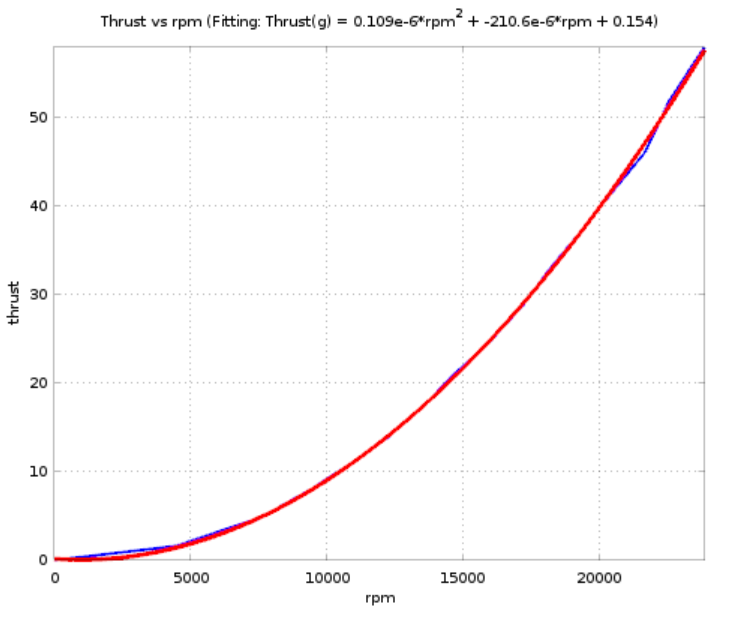

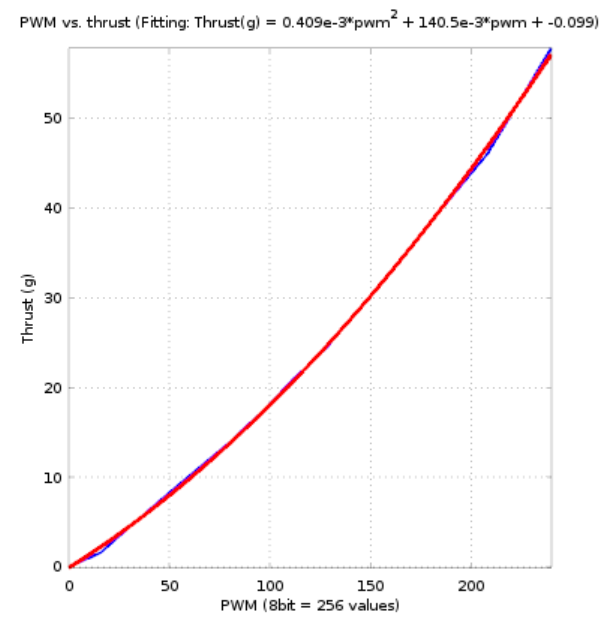

syms thrust pwm rpm 

pwm_to_thrust(pwm) = 0.409e-3*pwm^2 + 140.5e-3*pwm + (-0.099)

$$pwm\_to\_thrust(pwm) = \frac{7544718326147207\,{\mathrm{pwm}}^{2}}{18446744073709551616}+\frac{281\,\mathrm{pwm}}{2000}-\frac{99}{1000}$$

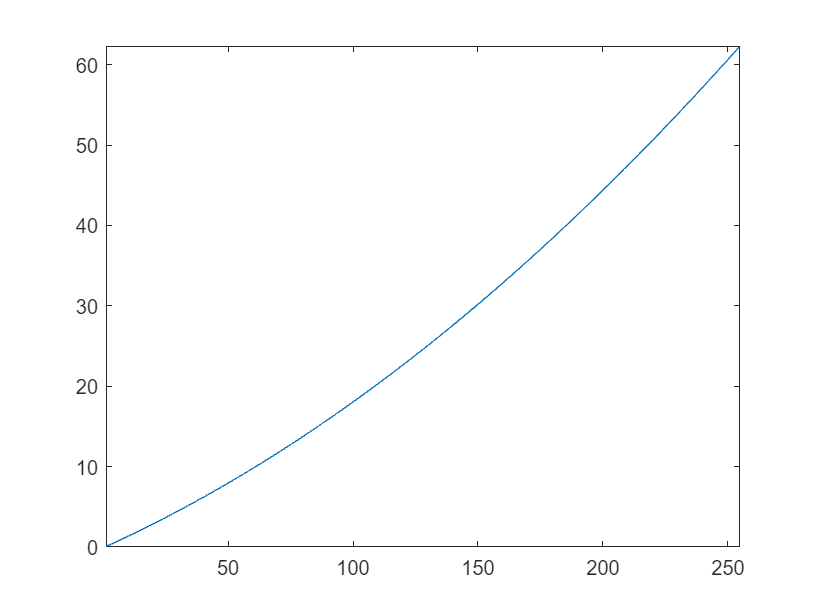


fplot(pwm_to_thrust(pwm),[1 255])


tr(rpm) = 0.109e-6*rpm^2 + (-210.6e-6)*rpm+0.154

$$tr(rpm) = \frac{8235807146124661\,{\mathrm{rpm}}^{2}}{75557863725914323419136}-\frac{7769768603846463\,\mathrm{rpm}}{36893488147419103232}+\frac{77}{500}$$

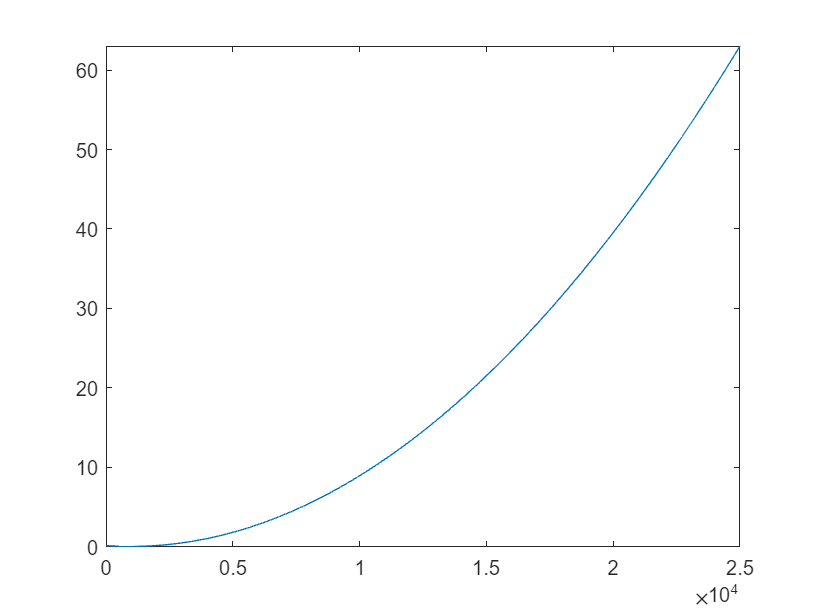


fplot(tr(rpm),[0 25000])



f1 = 0.409e-3*pwm^2 + 140.5e-3*pwm + (-0.099)

$$f1 = \frac{7544718326147207\,{\mathrm{pwm}}^{2}}{18446744073709551616}+\frac{281\,\mathrm{pwm}}{2000}-\frac{99}{1000}$$

f2 = 0.109e-6*rpm^2 + (-210.6e-6)*rpm+0.154

$$f2 = \frac{8235807146124661\,{\mathrm{rpm}}^{2}}{75557863725914323419136}-\frac{7769768603846463\,\mathrm{rpm}}{36893488147419103232}+\frac{77}{500}$$



eq1 = thrust == f1

$$eq1 = \mathrm{thrust}=\frac{7544718326147207\,{\mathrm{pwm}}^{2}}{18446744073709551616}+\frac{281\,\mathrm{pwm}}{2000}-\frac{99}{1000}$$

eq2 = thrust == f2

$$eq2 = \mathrm{thrust}=\frac{8235807146124661\,{\mathrm{rpm}}^{2}}{75557863725914323419136}-\frac{7769768603846463\,\mathrm{rpm}}{36893488147419103232}+\frac{77}{500}$$


rpm(thrust) = vpasolve(eq2,rpm)

$$rpm(thrust) = \left(\begin{array}{c} 966.05504587155964517853530406993-4587155.9633027524343181985892006\,\sqrt{0.00000043599999999999998662292386049366\,\mathrm{thrust}-0.000000022791639999999999545786972133393}\\ 4587155.9633027524343181985892006\,\sqrt{0.00000043599999999999998662292386049366\,\mathrm{thrust}-0.000000022791639999999999545786972133393}+966.05504587155964517853530406993 \end{array}\right)$$



rpm(2)

$$ans = \left(\begin{array}{c} -3261.1239387667373090983894315362\\ 5193.234030509856599455460039676 \end{array}\right)$$


pwm2rpm = matlabFunction(rpm(f1))

pwm2rpm = function_handle with value:
    @(pwm)[sqrt(pwm.*6.1258e-8+pwm.^2.*1.78324e-10-6.595564e-8).*-4.587155963302752e+6+9.660550458715596e+2;sqrt(pwm.*6.1258e-8+pwm.^2.*1.78324e-10-6.595564e-8).*4.587155963302752e+6+9.660550458715596e+2]



pwm2rpm(20)

ans = 1.0e+03 *

   -4.1225
    6.0546




%solve(eq2,rpm)


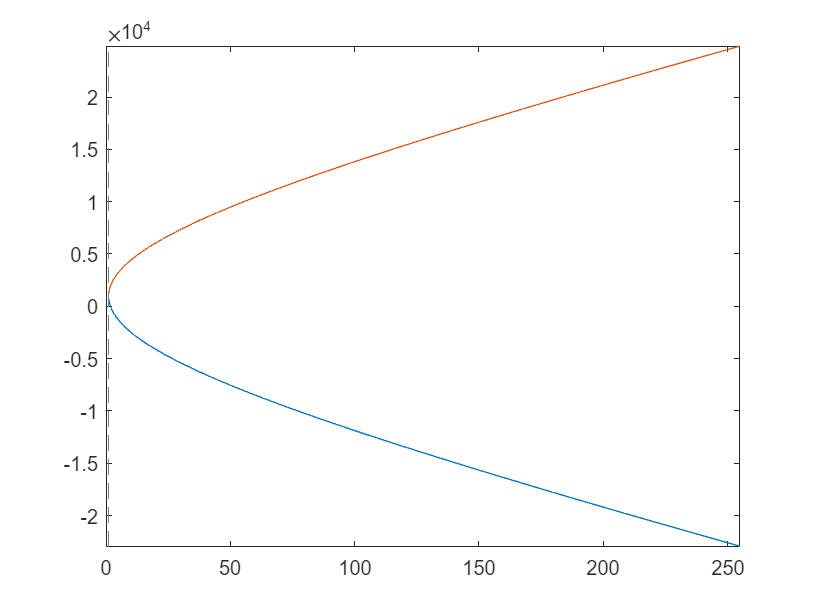



fplot(rpm(f1),[0 255])


C_T = 0.055; 

    C_Q = 0.024

C_Q = 0.0240

    
    air_density = 1.293; %kg/m^3
    
    propeller_radius = 0.045/2; %m
     
    disc_area = pi*propeller_radius^2% - pi*0.002^2

disc_area = 0.0016


syms rpm 


thrust_from_rpm(rpm) = air_density*C_T*disc_area*propeller_radius^2*(rpm*0.1047198)^2

$$thrust\_from\_rpm(rpm) = \frac{15396356901960413319380616422888040744449539771\,{\mathrm{rpm}}^{2}}{24519928653854221733733552434404946937899825954937634816}$$


round(thrust_from_rpm(20000),5)

$$ans = 0.25116$$


round((tr(20000)*0.001*9.82)/4,5)

$$ans = 0.09708$$

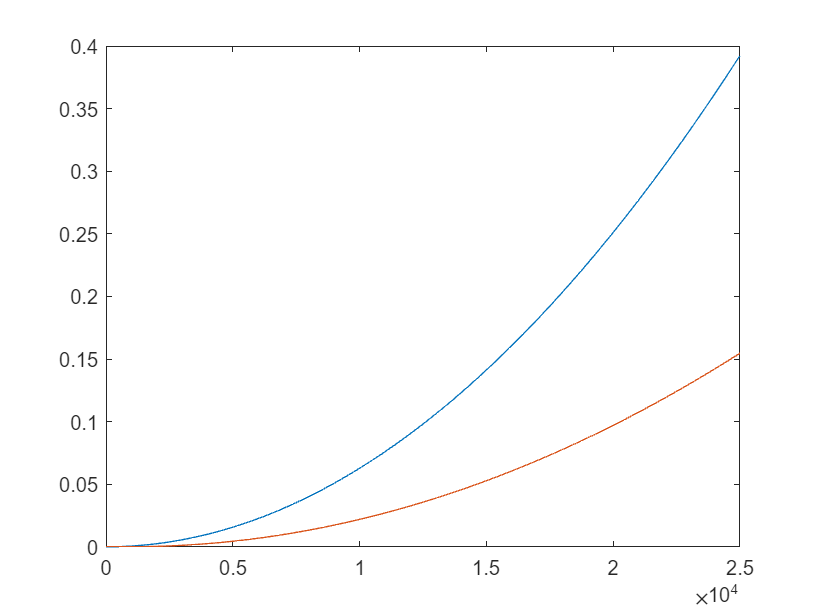


fplot(thrust_from_rpm(rpm),[0 25000])
hold on 
fplot(tr(rpm)*0.001*9.82*0.25,[0 25000])
hold off 



rpm2torque(rpm) = air_density * C_Q * disc_area * propeller_radius^3 * (rpm*0.1047198)^2

$$rpm2torque(rpm) = \frac{38698043238672864945537258237515028453907184755\,{\mathrm{rpm}}^{2}}{6277101735386680763835789423207666416102355444464034512896}$$


round(rpm2torque(20000),5)

$$ans = 0.00247$$



thrust=0.1

thrust = 0.1000


4587155.9633027524343181985892006*sqrt(0.00000043599999999999998662292386049366*thrust - 0.000000022791639999999999545786972133393)x+966.05504587155964517853530406993; 

